Back scattering effect


$$B_c =B_c^{\infty } \left(1-e^{-\beta_c^B {\left(v_B \right)}z} \right)$$


where, $\beta_c^B =-\ln {\left[1-\frac{\int_{\lambda_1 }^{\lambda_2 } S_c \left(\lambda \right)B^{\infty } \left(\lambda \right)\left(1-e^{-\beta {\left(\lambda \right)}z} \right)d\lambda }{\int_{\lambda_1 }^{\lambda_2 } S_c \left(\lambda \right)B^{\infty } \left(\lambda \right)d\lambda }\right]}/z$, $B^{\infty } {\left(\lambda \right)}=\frac{b{\left(\lambda \right)}E\left(d,\lambda \right)}{\beta {\left(\lambda \right)}}$

clear; clc;

#### Ocean IOP

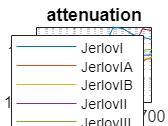

load("mat data\Ocean_IOP_Jerlov.mat")
a_Jerlov = a_Jerlov(5:17,:);
b_Jerlov = b_Jerlov(5:17,:);

plot (400:25:700, beta_Jerlov(5:end,:))
grid on
set(gca, 'YScale', 'log')
title('attenuation')
typename = {'JerlovI','JerlovIA','JerlovIB','JerlovII','JerlovIII','Jerlov1C','Jerlov3C','Jerlov5C'};
legend(typename)

beta_Jerlov = beta_Jerlov(5:17,:);


#### Background light source E(d, $\lambda$)

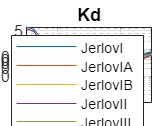

% load Kd of Jerlov's
load("mat data\Kd_database.mat");
plot (300:25:700, Kd_Jerlov)
set(gca, 'YScale', 'log')
title ('Kd')
yticks([0.1 0.2 0.3 0.4 0.5 1 5 10])
grid on
legend(typename)

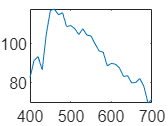

Kd_Jerlov = Kd_Jerlov(5:17,:);

% depth
d = [1 5];

% background light (D65 white)
[x, E0] = illuminant('d65');
plot(x(101:401),E0(101:401))

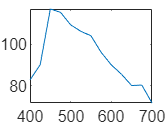

E0 = E0(101:25:401);
x = x(101:25:401);
plot(x,E0)

for i = 1:numel(typename)
    for j = 1:numel(d)
        Kd = Kd_Jerlov(:,i);
        Ed_Jerlov(:,i,j) = E0.* exp(-Kd(:)*d(j));
    end
end

#### Sc : 25 cameras, 3 bands

wavelength : 400:10:720 nm

load("mat data\Sc_database.mat")
for i = 1:7
    Sc_new(:,2*i-1,:) = Sc(:,1+5*(i-1),:);
    if i ~= 7
        Sc_new(:,2*i,:) = (Sc(:,3+5*(i-1),:) +  Sc(:,4+5*(i-1),:))/2;
    end
end

% AVERAGE of 28 cameras
Sc_new = mean(Sc_new,3);

% cemara RGB tristimulus value
Sc_R = Sc_new(1,:);
Sc_G = Sc_new(2,:);
Sc_B = Sc_new(3,:);

Plot camera Spectral Sensity

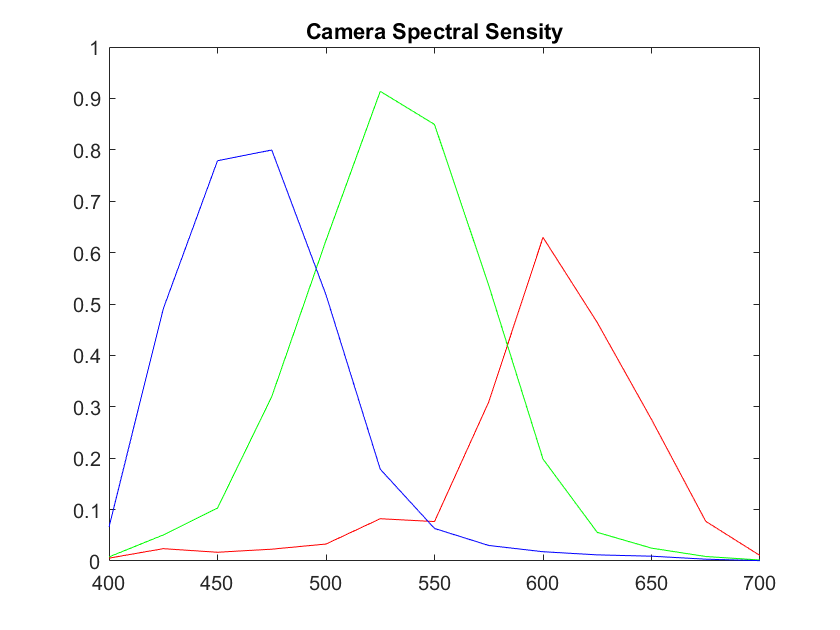

figure
plot(400:25:700, Sc_R,'r')
hold on
plot(400:25:700, Sc_G,'g')
hold on
plot(400:25:700, Sc_B,'b')
title('Camera Spectral Sensity')
set(gcf,'Visible','on')

#### Veiling Light $B_c^{\infty } {\left(\lambda \right)}$


$$B_c^{\infty } =\int_{\lambda_1 }^{\lambda_2 } S_c \left(\lambda \right)\frac{b{\left(\lambda \right)}E\left(d,\lambda \right)}{\beta {\left(\lambda \right)}}d\lambda$$
 

#### XYZ tristimulus value

[lambda_2, xFcn, yFcn, zFcn] = colorMatchFcn('cie_1931');
num = 400:25:700;
for i = 1:length(num)
    n(i,:) = find(round(lambda_2)==round(num(i)));
end

for j = 1:length(n)
    xFcn_new(j) = xFcn(n(j));
    yFcn_new(j) = yFcn(n(j));
    zFcn_new(j) = zFcn(n(j));
end
xyzFcn_new = [transpose(xFcn_new) transpose(yFcn_new) transpose(zFcn_new)];

#### Calculate veiling light

% method 2 : 使用CIE
Veil_Light = b_Jerlov./beta_Jerlov.*Ed_Jerlov;
Veil_Light= permute(Veil_Light,[1 4 2 3]);
N = dot(E0',yFcn_new);
% sum(Veil_Light .* xyzFcn_new)
Veil_Light_CIEXYZ = sum(Veil_Light .* xyzFcn_new)./N;

#### CIE XYZ to linear RGB

for i = 1:2 % depth
    for j = 1:8 % Jerlov
         Veil_Light_linear(:,j,i) = xyz2rgb(Veil_Light_CIEXYZ(:,:,j,i),'ColorSpace','linear-rgb')';
    end
end

xMin = 0;
% Clip to xMax
Veil_Light_linear(Veil_Light_linear<xMin) = xMin;

#### save veiling light to mat. 

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\mat data\';
save(strcat(fpath, "Colorchecker02_Veiling_Light_RGB_linear_1m5m_BLACK.mat"),"Veil_Light_linear")

#### Backscatter attenuation coefficient


$$\beta_c^B =-\ln {\left[1-\frac{\int_{\lambda_1 }^{\lambda_2 } B_c^{\infty } \left(\lambda \right)\left(1-e^{-\beta {\left(\lambda \right)}z} \right)d\lambda }{\int_{\lambda_1 }^{\lambda_2 } B_c^{\infty } \left(\lambda \right)d\lambda }\right]}/z$$
      

#### object distance

for i = 1:10
    z(:,:,i) = repmat(i,size(beta_Jerlov));
end

#### Two methods to calculate backscatter attenuation coefficient

% method 2
for j = 1:10
    for i = 1:numel(d)
        Veil_Light_infinity = Veil_Light(:,:,:,i) .* xyzFcn_new;
        Veil_Light_infinity = permute(Veil_Light_infinity,[1 3 2]);
        att_back(j,:,i,:) = -log(1 - sum( Veil_Light_infinity .* ( 1 - exp(-beta_Jerlov.*z(:,:,j)))) ./ sum( Veil_Light_infinity) )./z(1,1,j);
    end
end

att_back_R = att_back(:,:,:,1);
att_back_G = att_back(:,:,:,2);
att_back_B = att_back(:,:,:,3);

#### save backscatter coefficient value to mat. 

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\mat data\';
save(strcat(fpath, "Colorchecker02_Attenuation_backscatter_BLACK.mat"),"att_back_R","att_back_G","att_back_B")

#### plot backscatter attenuation coefficient

att_back_R_PLOT = reshape(att_back_R(10,:,:,:),[numel(att_back_R)/10 1]);
att_back_G_PLOT = reshape(att_back_G(10,:,:,:),[numel(att_back_G)/10 1]);
att_back_B_PLOT = reshape(att_back_B(10,:,:,:),[numel(att_back_B)/10 1]);

plot_type = repmat(typename,[1 2])

plot_type = 1×16 cell array
    {'JerlovI'}    {'JerlovIA'}    {'JerlovIB'}    {'JerlovII'}    {'JerlovIII'}    {'Jerlov1C'}    {'Jerlov3C'}    {'Jerlov5C'}    {'JerlovI'}    {'JerlovIA'}    {'JerlovIB'}    {'JerlovII'}    {'JerlovIII'}    {'Jerlov1C'}    {'Jerlov3C'}    {'Jerlov5C'}


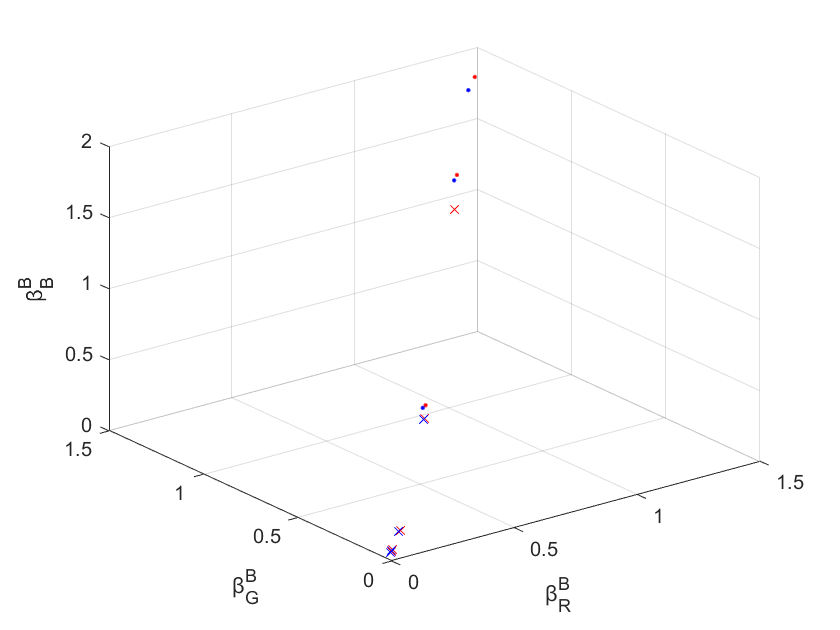

for i = [1 2 3 4 5 ]
    plot3(att_back_R_PLOT(i),att_back_G_PLOT(i),att_back_B_PLOT(i),'rx')
    hold on
    plot_type{i} = strcat(plot_type{i},' depth 1m');
end
for i = [6 7 8 ]
    plot3(att_back_R_PLOT(i),att_back_G_PLOT(i),att_back_B_PLOT(i),'r.')
    hold on
    plot_type{i} = strcat(plot_type{i},' depth 1m');
end

for i = [9 10 11 12 13 ]
    plot3(att_back_R_PLOT(i),att_back_G_PLOT(i),att_back_B_PLOT(i),'bx')
    hold on
    plot_type{i} = strcat(plot_type{i},' depth 5m');
end
for i = [14 15 16]
    plot3(att_back_R_PLOT(i),att_back_G_PLOT(i),att_back_B_PLOT(i),'b.')
    hold on
    plot_type{i} = strcat(plot_type{i},' depth 5m');
end
grid on
% legend(plot_type)
xlabel('β_R^B')
ylabel('β_G^B')
zlabel('β_B^B')
set(gcf,'Visible','on')

#### Backscatter effect image


$$B_c =B_c^{\infty } \left(1-e^{-\beta_c^B {\left(v_B \right)}z} \right)$$


% object distance
zz = [1:10];
for i = 1 : numel(d)
    for j = 1:8
        
    BackScatter_R_linear(:,j,i) = Veil_Light_linear(1,j,i) .* ( 1 - exp(-att_back_R(:,j,i) .* zz' ));
    BackScatter_G_linear(:,j,i) = Veil_Light_linear(2,j,i) .* ( 1 - exp(-att_back_G(:,j,i) .* zz' ));
    BackScatter_B_linear(:,j,i) = Veil_Light_linear(3,j,i) .* ( 1 - exp(-att_back_B(:,j,i) .* zz' ));
    end
end



#### Source the data

BackScatter_R_1m =  lin2rgb(BackScatter_R_linear(:,:,1));
BackScatter_R_5m =  lin2rgb(BackScatter_R_linear(:,:,2));
BackScatter_G_1m =  lin2rgb(BackScatter_G_linear(:,:,1));
BackScatter_G_5m =  lin2rgb(BackScatter_G_linear(:,:,2));
BackScatter_B_1m =  lin2rgb(BackScatter_B_linear(:,:,1));
BackScatter_B_5m =  lin2rgb(BackScatter_B_linear(:,:,2));

#### plot the backscatter effect

typename = split(typename,'Jerlov');
fpath = '資料整理\Bc_image\'

fpath = '資料整理\Bc_image\'

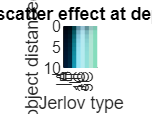


plotcolorpatch(BackScatter_R_1m, BackScatter_G_1m, BackScatter_B_1m)
% set(gcf,"Visible","on")
title('Backscatter effect at depth 1m')
xlabel('Jerlov type')
xticks([1:8])
xticklabels(typename(:,:,2))
ylabel('object distance(m)')
set (gca,'Ydir','reverse')

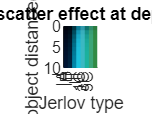

% saveas(gcf,strcat('Bc at depth ',num2str(1)),'bmp')

plotcolorpatch(BackScatter_R_5m, BackScatter_G_5m, BackScatter_B_5m)
% set(gcf,"Visible","on")
title('Backscatter effect at depth 5m')
xlabel('Jerlov type')
xticks([1:8])
xticklabels(typename(:,:,2))
ylabel('object distance(m)')
set (gca,'Ydir','reverse')

% saveas(gcf,strcat('Bc at depth ',num2str(5)),'bmp')


#### save backscatter value to mat. 

fpath = 'C:\Users\lingoiapple\OneDrive - 國立台灣大學\JJJ\11 碩一 上下 2021-2022\study_水下攝影測量\水下攝影測量\04 計畫\模擬資料\mat data\';
save(strcat(fpath, "Colorchecker02_Backscatter_RGB_linear_1m5m_BLACK.mat"),"BackScatter_R_linear","BackScatter_G_linear","BackScatter_B_linear")

function plotcolorpatch(R,G,B)
Nr_R = R;
Nr_G = G;
Nr_B = B;
%%
x = 0 : 8;
y = 0 : 10;
%% 網格xy首末
x1 = [x(1) x(end)]';
y1 = [y(1) y(end)]';

%% 繪製網格
figure
% 填色至各網格
for i = 1:10
    for j = 1:8
        xx = [0 1 1 0] + j - 1;
        yy = [0 0 1 1] + i - 1;
        patch("XData", xx, 'yData', yy, 'FaceColor', [Nr_R(i,j) Nr_G(i,j) Nr_B(i,j)],'LineStyle',"none");
    end
end

axis equal
xlim(x1)
ylim(y1)
end